# Test for get_height()

% initializing filename and reference height
filename = 'cup_test_white_ background.jpg';
reference_height = 6;

% demonstration of regionprops() and edges()
image = imread(filename)

image = 460×860×3 uint8 array
image(:,:,1) =

   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   250   249   249   249   250   249   249   249   249   249   250   250   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249

bw_cup = rgb2gray(image);
cup_edges = edge(bw_cup);
cup_stats = regionprops(cup_edges);

% 
initial_guess = [400,1000]

initial_guess =          400        1000


clean_cup = bwareafilt(cup_edges, [400,1000])

clean_cup = 460×860 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

figure, imshow(clean_cup)
prop_stats = regionprops(clean_cup)

prop_stats = 3×1 struct array with fields:
    Area
    Centroid
    BoundingBox


BB = struct2cell(prop_stats)

BB = 3×3 cell array
    {[     971]}    {[     698]}    {[     519]}
    {1×2 double}    {1×2 double}    {1×2 double}
    {1×4 double}    {1×4 double}    {1×4 double}


bounding_box = BB(3,:)

bounding_box = 1×3 cell array
    {1×4 double}    {1×4 double}    {1×4 double}


water_info = bounding_box{3}

water_info =   337.5000  106.5000  185.0000  291.0000


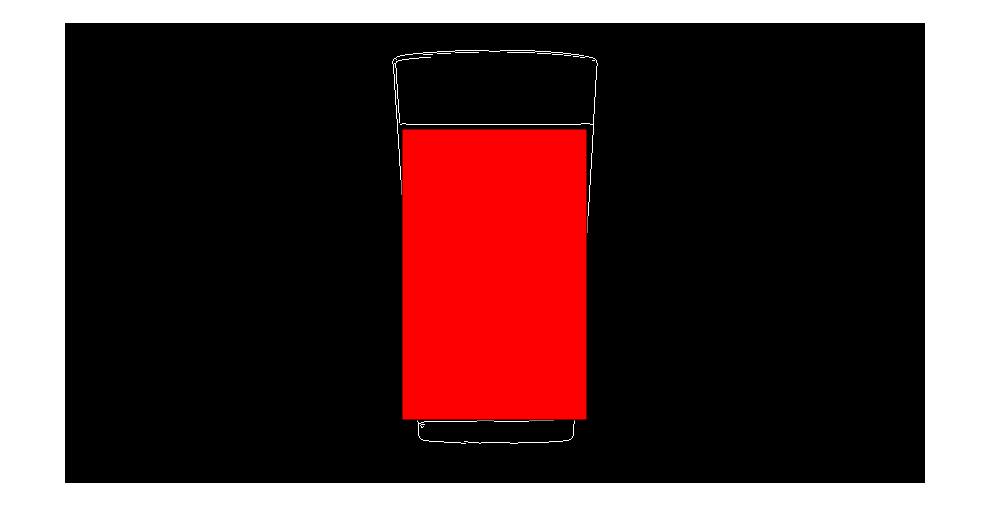


hold on 
% Showing how to use region props to find appropriate area
rectangle('Position', water_info, 'FaceColor', 'r')


% ultimately, this funciton will need to be written into a loop to loop
% over all images in an experimental run 

abs_heights = get_height(filename, reference_height,initial_guess)

abs_heights =     6.0000
    5.9086
    4.4315



% Might also want to put Tank 1, Tank 2, Tank 3, Tank 4 into different
% arrays dynamically then write to csv